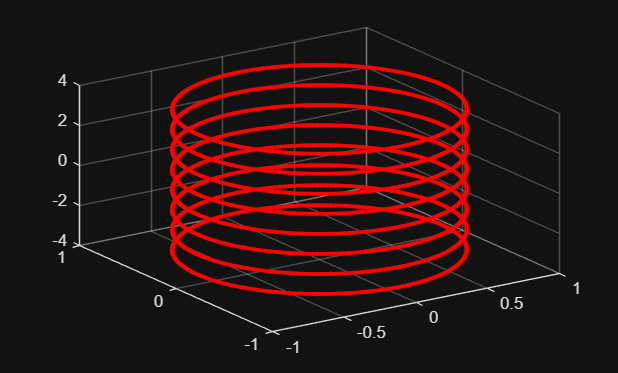

addpath('C:\Users\yared\Documents\MATLAB\Freno Magnético')

nl = 8; % número de espiras
N = 200; % Puntos en las espiras
R = 0.85; % Radio
R_circuito = 0.001;
sz = 1; % Distancia entre espiras
I = 1000; % Corriente
I_efectiva = I * N;
mo = 4*pi*1e-7; % Permeanilidad magnética
km = mo * I_efectiva / (4*pi); % Constante de Biot-Savart
rw = 0.2; % Constante de Biot-Savart
ds = 0.01; % Grosor entre los puntos de la malla
zo = 4.9;
dt = 0.01;
mag = 1035;
gamma = 0.08;
m = 0.05;
vz = 1;
r = 1e-5;
B_ring = 1;

plot_option = true;
%ds = 0.05;

[Px,Py,Pz,dx,dy,dz] = espiras(sz,nl,N,R);

%[Bz,z] = campoB(ds,km,Px,Py,Pz,dx,dy,nl,N,rw,plot_option);

plot_option = false

plot_option = logical
   0


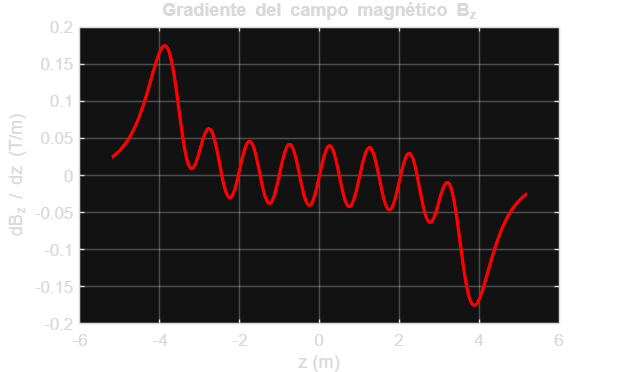


[Bz,z,dPhi_dz] = campoB(ds,km,Px,Py,Pz,dx,dy,nl,N,rw,plot_option,R);


disp(max(abs(dPhi_dz)))

    0.5654



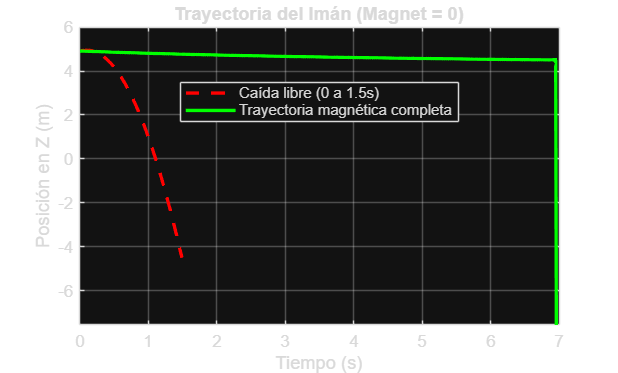

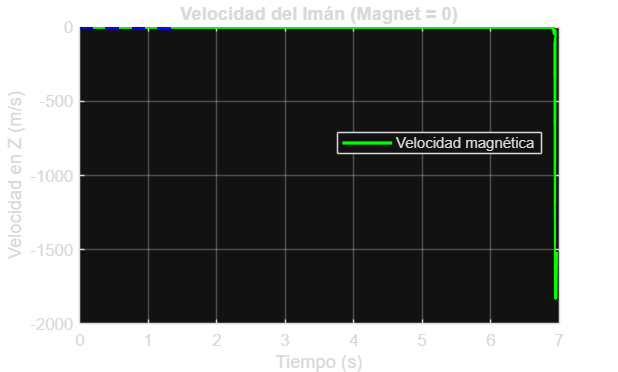

zm =     4.9000    4.9064    4.9086    4.9089    4.9084    4.9075    4.9064    4.9053    4.9041    4.9029    4.9017    4.9005    4.8993    4.8981    4.8969    4.8957    4.8945    4.8934    4.8922    4.8910    4.8899    4.8887    4.8876    4.8864    4.8853    4.8841    4.8830    4.8818    4.8807    4.8796    4.8785    4.8773    4.8762    4.8751    4.8740    4.8729    4.8718    4.8707    4.8696    4.8685    4.8674    4.8664    4.8653    4.8642    4.8631    4.8621    4.8610    4.8600    4.8589    4.8578



magnet = false;

zm = Trayectoria(Bz,z,mag,m,zo,dt,vz,gamma,magnet,dPhi_dz,R_circuito)